clear
clc
clf
number_of_followers = 40;
number_of_virtual = 1;
rng(1555)

#### Defining the leader

deltat = 0.0001;
time_steps = 0:deltat:50+0.999;
r0 = [time_steps;-5+10*sin(time_steps*pi/25)].';
r0_reshaped = zeros(1,2);
for i=1:size(r0,1)
    r0_reshaped(:,:,i) = r0(i,:);
end
r0_reshaped;

random_coords = randn(number_of_followers,2);
r_i = zeros(number_of_followers+number_of_virtual,2,size(time_steps,2));
r_i(2:end,:,1)= [(random_coords(:,1)*5.5)-6 (random_coords(:,2)*8.1)];
r_i(1,:,:) = r0_reshaped;
size(r_i)

ans =           41           2      509991


adj_matrix = find_adj(r_i(:,:,1),3)

adj_matrix =      0     0     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     1     0

g = graph(adj_matrix)

g =   graph with properties:

    Edges: [56×2 table]
    Nodes: [41×0 table]


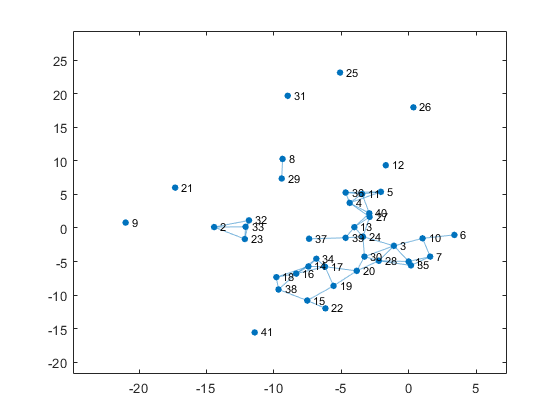

plot(g,"XData",r_i(:,1,1),"YData",r_i(:,2,1))

## Equation to follow 

## 
$$u_i = -\alpha\sum_{j\in\bar{\mathcal{N}}_i(t)}\frac{\partial{V_{ij}}}{\partial{r_i}}-\beta sgn(\sum_{j\in\bar{\mathcal{N}}_i(t)}\frac{\partial{V_{ij}}}{\partial{r_i}})$$


where 

### 
$$\frac{\partial{V_{ij}}}{\partial{r_i}} =\begin{cases}0, \|r_i-r_j\|>R\\\frac{2\pi(r_i-r_j)\sin{2*\pi(\|r_i-r_j\|-d_{ij})}}{\|r_i-r_j\|}, d_{ij}\lt\|r_i-r_j\|\leq R\\\frac{20(r_i-r_j)}{\|r_i-r_j\|}\frac{\|r_i-r_j\|-d_{ij}}{\|r_i-r_j\|}, \|r_i-r_j\|\leq d_{ij}\end{cases}$$


R = 4;
dij = 2;
alpha = 1;
beta = 3;

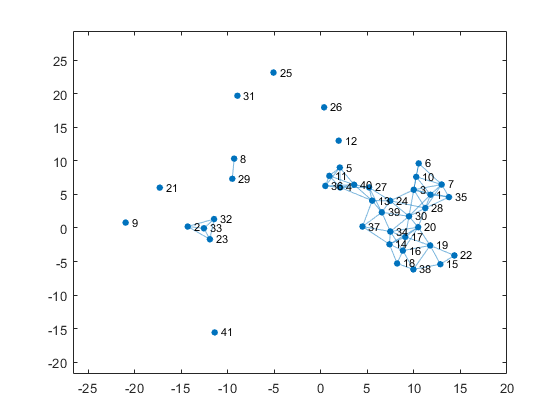

r_dot = zeros(size(r_i,1)-1,2);
for t=1:size(r_i,3)
    adj_matrix = find_adj(r_i(:,:,t),R);
    for i=2:size(r_i,1)
        temp_sum = 0;
        for j=1:size(r_i,1)
            if(adj_matrix(i,j)>0)
               temp_sum = temp_sum + potential(r_i(i,:,t),r_i(j,:,t),R,dij); 
            end
        end
        r_dot(i-1,:) = -alpha*temp_sum - beta*sign(temp_sum);
    end
    r_i(2:end,:,t+1) = r_i(2:end,:,t)+(r_dot*deltat);
    if(mod(t,100)==0)
        g = graph(adj_matrix);
       plot(g,'XData',r_i(:,1,t),'YData',r_i(:,2,t));
        pause(0.00005) 
    end
end

clf
hold off
for i=1:size(r_i,3)
%     adj_matrix = find_adj(r_i(:,:,i),R);
%     g = graph(adj_matrix);
    plot(g,'XData',r_i(:,1,i),'YData',r_i(:,2,i));
            pause(0.00005) 
end

function a = find_adj(r,R)
    a = zeros(size(r,1));
    for i=1:size(r,1)
        temp = nset(r(i,:),r(:,:),R);
        a(i,:) = temp;
        a(i,i) = 0;
    end
end
 function n = potential(ri,rj,R,dij)
    dist = pdist([ri;rj],"euclidean");
    if(dist >R)
        n=0;
    elseif((dist <=R) && (dist >dij))
        n = ((2*pi*(ri-rj)*sin(2*pi*(dist-dij)))/(dist));
    else
        n = ((20*(ri-rj))/dist)*((dist-dij)/dist);
    end
 end
function n = nset(ri,rj,R)
    size(rj,1);
    n_temp=pdist([ri;rj],"euclidean")<R;
    n = n_temp(1:size(rj,1));
end